# Conducción de Calor a Través de una Barra de Hierro

Este ejemplo muestra cómo los bloques térmicos pueden modelar una barra larga de hierro que está fija a una base caliente en un extremo y expuesta al aire a lo largo de su longitud y en su extremo libre. La barra es una superficie extendida que experimenta **conducción a lo largo de su longitud **y c**onvección con el aire en la dirección **perpendicular** a su longitud**. Las superficies extendidas se utilizan a menudo como aletas para enfriar un sólido.

En este escenario, la base está fijada a una pared con una temperatura de 1**00 grados Celsius**. El calor se transfiere a lo largo de la barra por conducción, calentando gradualmente la masa térmica de la barra. El calor se escapa de la superficie cilíndrica de la barra y del extremo libre por convección natural con el aire ambiente, que tiene una temperatura de **20 grados Celsius**. I**nicialmente, la temperatura de toda la barra es igual a la temperatura del aire ambiente**. La t**emperatura a lo largo de la barra alcanza el estado estacionario después de aproximadamente 1500 segundos**. La barra está hecha de **hierro,** tiene **20 cm de longitud y 2,5 cm de diámetro.**

Este ejemplo describe inicialmente los efectos térmicos fundamentales en la barra: la ley que rige la **conservación de la energía, los mecanismos de transferencia de calor por conducción y convección, y la propiedad de la masa térmica**. Luego, este ejemplo combina los efectos térmicos para considerar dos modelos térmicos completos de la barra. **El primer modelo térmico **contiene **una sola masa concentrada**, mientras que el **segundo es un modelo de** **diferencias finitas con múltiples masas concentradas**. Este ejemplo considera los compromisos entre el costo computacional y la fidelidad de los dos modelos térmicos diferentes para la barra. Este ejemplo compara qué tan bien convergen los modelos con la solución analítica en **estado estacionario**.

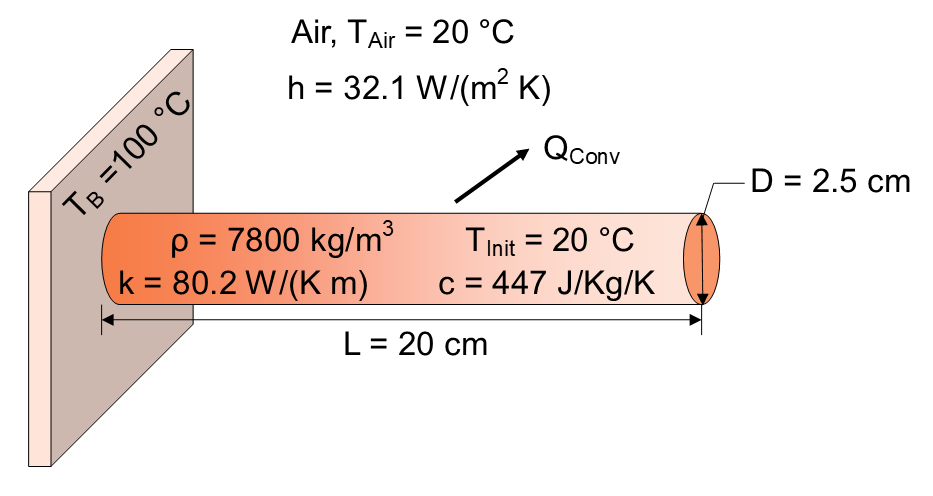

**Parámetros del modelo**

clear
% Condiciones térmicas
T_air     = 20;        % Temperatura del aire           [°C]
T_base     = 100;       % Temperatura de la base         [°C]
T_ini      = T_air;    % Temperatura inicial de la barra [°C]

% Parámetros geométricos
L          = 0.2;       % Longitud de la barra           [m]
D          = 0.025;     % Diámetro de la barra           [m]
A          = pi*D^2/4;  % Área de sección transversal de la barra [m^2]
A_cyl      = pi*D*L;    % Área superficial cilíndrica de la barra [m^2]

% Propiedades del material (hierro)
rho        = 7800;      % Densidad del hierro            [kg/m^3]
k          = 80.2;      % Conductividad térmica del hierro [W/(K·m)]
h          = 32.1;      % Coeficiente de transferencia de calor por convección [W/(m^2·K)]
c          = 447;       % Calor específico del hierro    [J/kg·K]

m          = rho*A*L;   % Masa de la barra               [kg]


## Ley de la Conservación de Energía

La primera ley de la termodinámica es un principio fundamental de la física que establece que la energía total de un sistema aislado permanece constante a lo largo del tiempo. Esta ley se expresa matemáticamente en términos de potencia como:

$\frac{dU}{dt} = Q - W$.

Donde:

- $\frac{\textrm{dU}}{\textrm{dt}}$ es la tasa de cambio de la energía interna respecto al tiempo (medida en W en unidades SI).

- $Q$ es la tasa de calor añadido al sistema (medida en W).

- $W$ es la tasa de trabajo realizado por el sistema (medida en W).

En sistemas térmicos donde no ocurre trabajo, la tasa de cambio de la energía interna es igual a la tasa de calor añadido al sistema:

$\frac{dU}{dt} = Q $.

En la barra de hierro, la transferencia de calor por conducción y convección($Q$) cambia la energía interna almacenada en la masa térmica de la barra ($U$).

## Conducción

La conducción térmica es el proceso de transferencia de calor a través de un material. Cuando el material se calienta, sus moléculas ganan energía cinética, lo que lleva a un aumento en su movimiento. Este movimiento incrementado provoca colisiones con moléculas vecinas, transfiriendo energía en el proceso. Esta transferencia continúa hasta que se alcanza el equilibrio térmico, resultando en una temperatura uniforme en toda la sustancia.

La ecuación de la conducción térmica, también conocida como la ley de Fourier, describe la tasa de transferencia de calor a través de un material:

$Q =k \frac{A}{L} (T_1 - T_2)$,

donde:

- $Q$ es el flujo de calor desde el extremo $1$ al extremo $2$ (medido en W).

- $k$ es la conductividad térmica del material (medida en *W/(K m)*).

- $A$ es el área normal a la dirección del flujo de calor (medida en m²).

- $L$  es el espesor en la dirección del flujo de calor (medido en m).

- $T_1$ and $T_2$ son las temperaturas en cada extremo del elemento de transferencia de calor por conducción (medidas en °C).

### Ejemplo 1 - Conducción en Estado Estacionario

Considera un escenario simplificado para la barra: La barra está aislada de modo que no hay transferencia de calor por convección con el aire a lo largo de su longitud. Un flujo constante de 18 W de calor atraviesa la barra y sale por la punta de la barra. ¿Cuál es la temperatura en la punta de la barra?

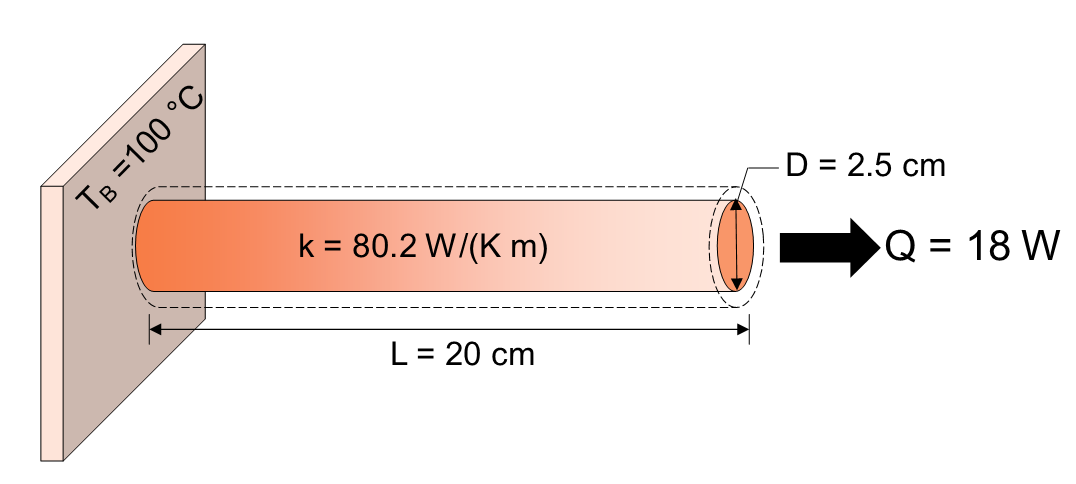

Reordenando la ecuación de conducción térmica, se espera que la temperatura en la punta de la varilla sea,


$$T_{End} =  T_{Base} - \frac{L}{A  k} Q$$


% Parámetro de ejemplo
Q_case_1  = 18;       % Tasa de flujo de calor a través de la varilla [W]

% Temperatura prevista en la punta de la varilla
T_rod_tip_steady_case_1 = T_base - L/(A*k)*Q_case_1 % [degC]

Abra el modelo HeatConductionThroughInsulatedIronRod para verificar la solución analítica. El modelo térmico consta de una fuente de temperatura configurada a la temperatura base, un elemento de transferencia de calor conductivo y una fuente de flujo de calor configurada a 18 W. O

mdl = 'HeatConductionThroughInsulatedIronRod';
open_system(mdl);

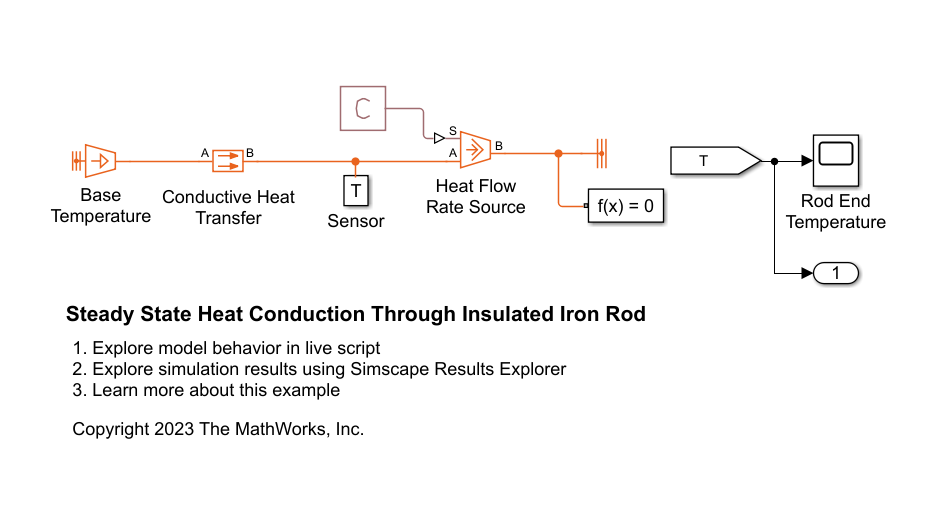

Simule el modelo y compare los resultados de la simulación con la solución analítica.

sim(mdl);
% Obtener el resultado de la simulación
T = yout; % [degC]

% Mostrar la temperatura
T_rod_tip_simulated_case_1 = T(end) % [degC]

Los resultados de la simulación concuerdan con la solución analítica.

## Convección

La convección es el proceso de transferencia de calor mediante el movimiento de un fluido. El movimiento del fluido, combinado con la conducción, conduce al transporte de energía térmica desde las regiones más calientes hacia las regiones más frías dentro del fluido. La convección natural ocurre en un fluido debido a diferencias de densidad causadas por gradientes de temperatura. Cuando un fluido se calienta, se vuelve menos denso y tiende a elevarse, mientras que el fluido más frío y denso se mueve para ocupar su lugar. Esto establece un patrón de circulación dentro del fluido, donde el calor se transporta desde las regiones más calientes hacia las más frías.

La ecuación de la convección térmica, conocida como la ley de enfriamiento de Newton, describe la tasa de transferencia de calor desde una superficie hacia el fluido circundante:

$Q =h  A _{Conv}(T_1 - T_2)$,

donde:

- $h$ es el coeficiente de transferencia de calor por convección (medido en *W/(K m^2)*).

- $A_{\textrm{Conv}}$  es el área de la superficie (medida en m²).

- $T_1$ and $T_2$ on las temperaturas de la superficie y del fluido circundante, respectivamente (medidas en °C).

### Ejemplo 2 - Convección en Estado Estacionario

Considera otro escenario simplificado para la barra. La temperatura de toda la barra se mantiene en 55 grados Celsius. La temperatura ambiente es de 20 grados Celsius, y el coeficiente de transferencia de calor por convección entre la barra y el aire es de 32.1 W/(m²·K). **¿Cuál es la tasa de transferencia de calor entre la superficie cilíndrica de la barra y el aire?**

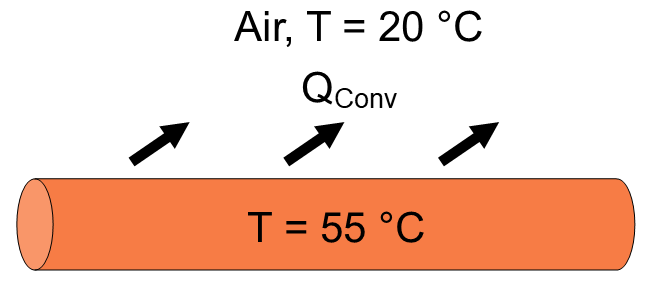

Sustituya los parámetros del modelo en la ecuación de convección térmica para calcular la tasa de transferencia de calor.

% Parámetro de ejemplo
T_cyl_uniform_case_2 = 55;       % Temperatura uniforme de la varilla [degC]

% Tasa esperada de transferencia de calor por convección
Q_conv_case_2 = h * A_cyl * (T_cyl_uniform_case_2 - T_air) % [W]

Utilice el modelo HeatConvectionFromIronRod para verificar la solución analítica. El modelo térmico consta de un elemento de transferencia de calor por convección entre una fuente de temperatura igual a la temperatura de la barra y una fuente de temperatura igual a la temperatura ambiente.

mdl = 'HeatConvectionFromIronRod';
open_system(mdl);

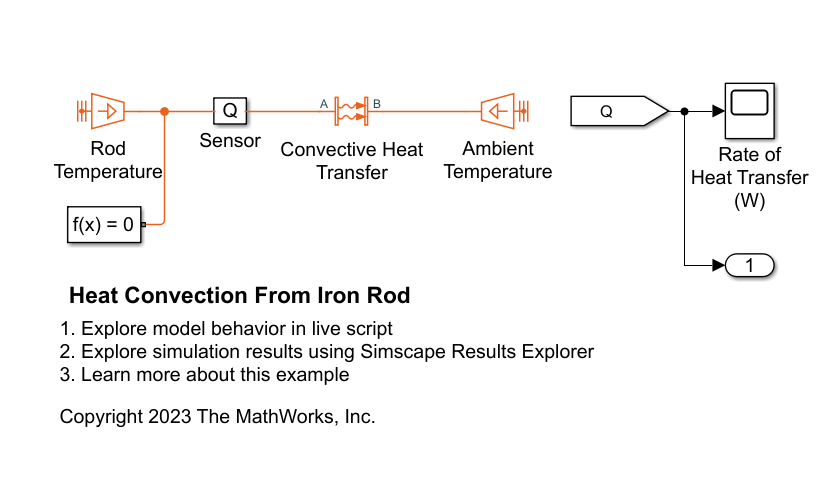

Simule el modelo y compare los resultados de la simulación con la solución analítica.

sim(mdl);

% Obtener el resultado de la simulación
Q = yout; % [W]

% Muestra la tasa de transferencia de calor.
Q_conv_simulated_case_2 = Q(end) % [W]

Los resultados de la simulación concuerdan con la solución analítica.

## Masa Térmica

La masa térmica refleja la capacidad de un material para almacenar y liberar energía térmica. El cambio en la energía interna de una masa térmica se representa mediante la ecuación:

$\frac{dU}{dt}= c  m \frac{dT}{dt}$,

donde:

- $\frac{\textrm{dU}}{\textrm{dt}}$ es la tasa de cambio de la energía interna respecto al tiempo (medida en W).

- $c$ es el calor específico del material (medido en *J/(Kg K)*).

- $m$ es la masa (medida en kg).

- $T$ es la temperatura (medida en °C o K).

La tasa de cambio de la energía interna del material, $U$, es proporcional a su tasa de cambio de temperatura,$T$. La capacidad calorífica específica, $c$, representa la cantidad de energía necesaria para cambiar la temperatura de una unidad de masa del material en un grado. Una gran masa térmica, $\textrm{cm}$, ralentiza los cambios de temperatura en un sistema.

### Ejemplo 3 - Respuesta Transitoria de Temperatura en una Masa Térmica

Considera un escenario simplificado de la barra. En este caso, 18 W de calor fluyen hacia una barra perfectamente aislada. Para simplificar, se asume que toda la barra se calienta de manera uniforme. ¿A qué ritmo aumentará la temperatura de la barra?

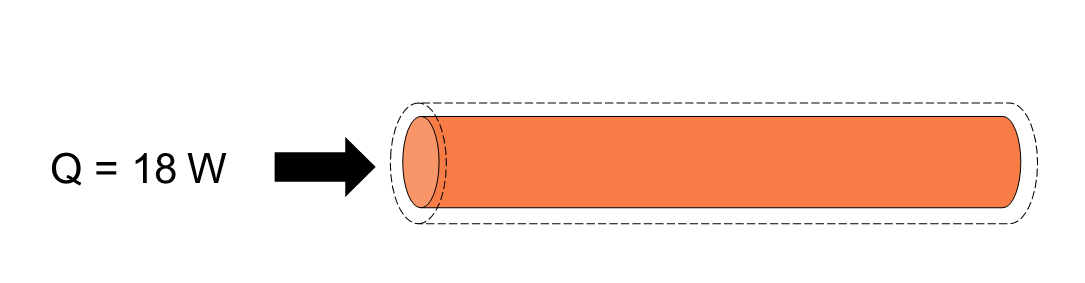

Utilizando la primera ley de la termodinámica, el calor que entra en la barra aislada es igual al cambio en la energía interna de la barra:

$Q = c  m \frac{dT}{dt}$.

Reordena la ecuación para resolver la tasa de cambio de la temperatura:

% Parámetro de ejemplo
Q_case_3  = 18;       % Tasa de flujo de calor a través de la varilla[W]
% Tasa esperada de cambio de temperatura
dT_dt_case_3 = Q_case_3 / (c*m) % Tasa de cambio de temperatura [degC/sec]

Utilice el modelo ThermalMassIronRod para verificar la solución analítica.

mdl = 'ThermalMassIronRod';
open_system(mdl);

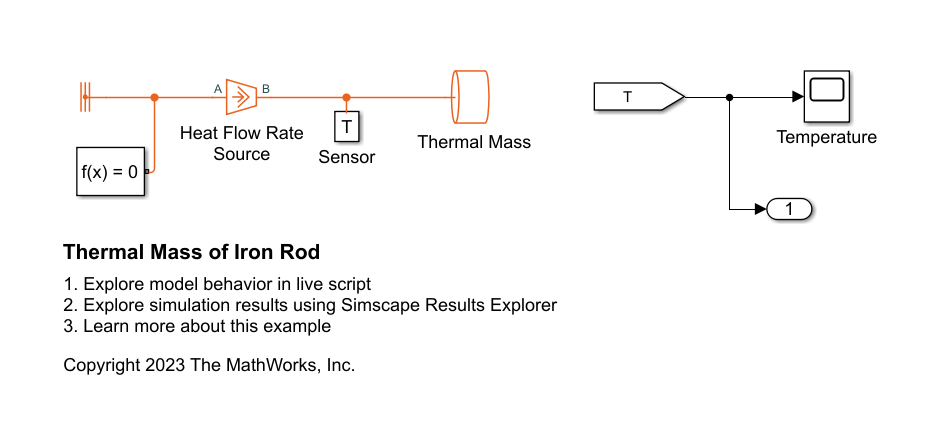

Simule el modelo y compruebe que los resultados de la simulación coinciden con la solución analítica.

sim(mdl);

% Obtener el resultado de la simulación
T = yout; % [degC]
t = tout; % [sec]

% Calcular la tasa de cambio de temperatura
dT = T(end) - T(1);
dt = t(end) - t(1);
dT_dt_simulated_case_3 = dT / dt % [degC/sec]

Los resultados de la simulación concuerdan con la solución analítica.

## Varilla con comportamiento térmico transitorio

Combine elementos de masa conductiva, convectiva y térmica para modelar completamente la varilla con comportamiento transitorio. La varilla tiene una temperatura base de 100 °C. Experimenta conducción térmica a lo largo de su longitud, así como convección térmica natural con el aire a lo largo de su longitud y en su extremo. Inicialmente, la temperatura de la varilla es igual a la temperatura ambiente de 20 °C. 

 on convergence. You can modify this example to add more segments. 

*Copyright 2008-2023 The MathWorks, Inc.*